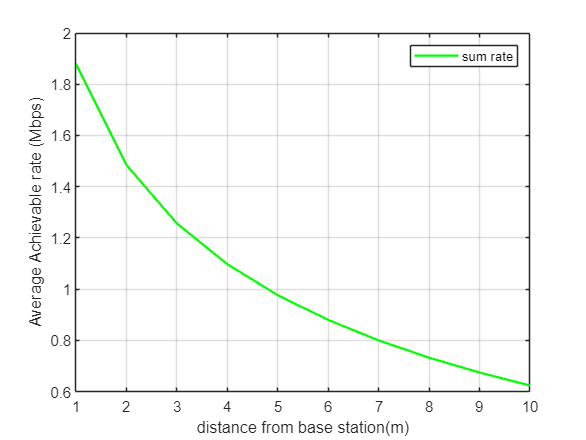

clc; clear variables; close all;

 
%source, 2 users. strong user acts as energy harvesting 
%relay to weak.  have direct path from BS to far user


N = 10^6;   

dsn = 1:1:10;   %Source to near user distance    
dsf = 1:1:10;   %Source to far user distance
dnf = dsf - dsn; %Near user to far user distance
eta = 2;    %Path loss exponent
%Rayleigh fading coefficients
hsn = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsn = (abs(hsn)).^2;
hsf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsf = (abs(hsf)).^2;
hnf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gnf = (abs(hnf)).^2;



Pt = 30;    % 发送功率（dBm）
pt = 10.^(Pt/10);    % 发送功率（线性尺度）
B = 1000000;
B1 = B/2;
N0_dBm=-60;                % Noise spectral density (in dBm/Hz)
N0=10^(N0_dBm/10)*B;          % Linear noise PSD in mW/Hz
N01 = (10^(N0_dBm/10))*B1;      %linear noise for swipt oma
snr = pt/N0;       %SNR in linear
snr1 = pt/(N01);       %SNR in linear(swipt oma)
SNR = 10*log10(snr);%SNR in dB
SNR1 = 10*log10(snr1);
 
%Power allocation factors
af = 0.8; an = 0.2;
R1 = 0.3; %Target rate for far user
t1 = (2^(2*R1))-1;   %target snr for both users
R2 = 1;   %target rate for near user
t2 = (2^(2*R2))-1;
eff = 0.7;  %power harvesting efficiency of the near user
frac = 0.4; %power splitting coefficient
del = 10^-6; %a small number

%Some buffers
pn = zeros(1,length(frac));
pf = zeros(1,length(frac));

csn = zeros(1,length(frac));
cfs = zeros(1,length(frac));
ph = zeros(1,length(frac));
sum_s = zeros(1,length(frac));

for u = 1:length(dsn)    
   
    

    %Amount of power harvested by near user
    ph = pt*gsn.*frac*eff/(1+dsn(u)^eta);
    

    %SNIR for each user
    
    sSNRn = (1-frac)*snr1.*gsn./(dsn(u)^eta);   %near user, swipt SNR
    sSNRf = (1-frac)*snr1.*gsf./(dsf(u)^eta);
   
    %Achievable rate of near user
 
    Rsn = 0.5*0.2*log2(1 + sSNRn);    %data rate for near user, swipt
  
    %Achievable rate of far user
 
    Rfs= 0.5*0.2*log2(1 + sSNRf);       %data rate for far user, swipt
 
    


    %calculate average rate for each user and the sum rate
 
    csn(u) = mean(Rsn);%swipt near
    cfs(u) = mean(Rfs);%swipt far
 

  
    sum_s(u) = csn(u) + cfs(u);%sum rate swipt
    
   

    
end

poutn1 = pn/N;
poutf1 = min(pf/N,1);

 

figure;
plot(dsn, sum_s, 'g', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
 
legend('sum rate');
xlabel('distance from base station(m)');
ylabel('Average Achievable rate (Mbps)');